# **Synthetic Data For Radar**

%Range (km) and height (km) of radar
range = linspace(0, 100, 100);
height = linspace(0, 10, 50);  

%Generates two 2D matrices, range and height, that represent all possible combinations of the range and height values.
[Range, Height] = meshgrid(range, height);

%Exponential decay with respect to range and height. As the range/height increases, the value decreases, simulating signal attenuation over distance.
propagation_factor = exp(-Range / 50) .* exp(-Height / 5); 
%This computes the ratio of height to range for each grid point, giving the slope of the radar wave's path.
%Units in radians
incidence_angle = atan(Height ./ Range); 
%Exponential decay of the refractive index with increasing height. This simulates how atmospheric conditions like temperature and pressure gradients affect the refractive index.
refractive_index = 1 + 0.0003 * exp(-Height / 5); 

%Reshaping data into column vectors and defining inputs and outputs
input_data = [reshape(propagation_factor, [], 1), reshape(incidence_angle, [], 1)];
target_data = reshape(refractive_index, [], 1);

%Creating a table for machine learning
data_table = table(input_data(:,1), input_data(:,2), target_data, ...
    'VariableNames', {'PropagationFactor', 'IncidenceAngle', 'RefractiveIndex'});
%Displays the first 5 rows of the data table
disp(data_table(1:5, :));

    PropagationFactor    IncidenceAngle    RefractiveIndex
    _________________    ______________    _______________

               1                NaN            1.0003     
         0.96001             1.5708            1.0003     
         0.92161             1.5708            1.0003     
         0.88475             1.5708            1.0003     
         0.84937             1.5708            1.0003     



# **First Machine Learning Algorithm Using SVM Regressor**

%Creating a hold-out cross-validation partition
%The 'cvpartition' function is used to split your data into training and testing sets for model validation.
%The 'hold-out, 0.2' specifies that 20% of the data will be held out as a test set, while the remaining 80% will be used as the training set.
cv = cvpartition(length(target_data), 'HoldOut', 0.2);

%Splitting input data into training and testing sets
train_data = input_data(training(cv), :);
test_data = input_data(test(cv), :);
%Splitting target data into training and testing sets
train_target = target_data(training(cv));
test_target = target_data(test(cv));

% My own SVM ML algorithm
SVRModel = fitrsvm(train_data, train_target, 'Standardize', true, 'KernelFunction', 'gaussian');

%Making predictions on test data
predicted_refractive_index = predict(SVRModel, test_data);

%Calculating mean squared error
mse = mean((predicted_refractive_index - test_target).^2); 
fprintf('Mean Squared Error: %.4f\n', mse);

Mean Squared Error: 0.0000


%Calculating R^2 score
SS_res = sum((test_target - predicted_refractive_index).^2);               
SS_tot = sum((test_target - mean(test_target)).^2);                        
r_squared = 1 - (SS_res / SS_tot);
fprintf('R² Score: %.4f\n', r_squared);

R² Score: 0.9396


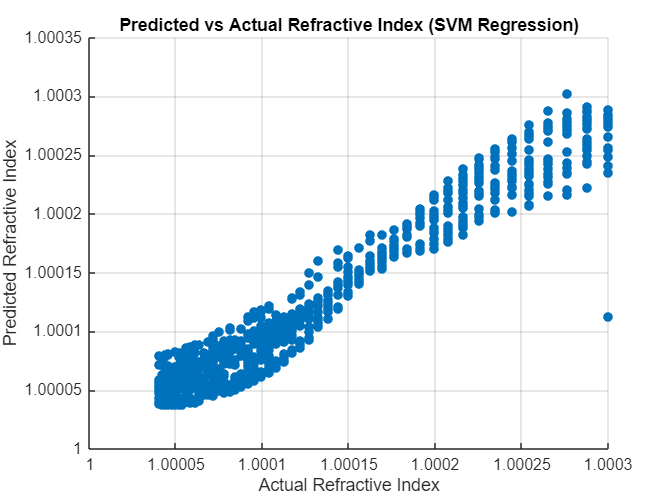

%Plot of predicted vs actual refractive index for SVM regression model
figure;
scatter(test_target, predicted_refractive_index, 'filled');
xlabel('Actual Refractive Index');
ylabel('Predicted Refractive Index');
title('Predicted vs Actual Refractive Index (SVM Regression)');
grid on;

# **Second Machine Learning Algorithm Using Fine Tree Model on Regression Learner**

% This is the Regression Learner Model I used which was a Tree model
disp(trainedModel)

           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'PropagationFactor'  'IncidenceAngle'}
       RegressionTree: [1×1 RegressionTree]
                About: 'This struct is a trained model exported from Regression Learner R2024b.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replace 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'




new_data = table(0.96001, 1.5708, 'VariableNames', {'PropagationFactor', 'IncidenceAngle'});
predicted_output = trainedModel.predictFcn(new_data);
disp('Predicted Output From Tree Model:');

Predicted Output From Tree Model:


disp(predicted_output);

    1.0003



rowsInRange = data_table(data_table.RefractiveIndex >= 1.07 & data_table.RefractiveIndex <= 1.08, :);
disp(rowsInRange);

    PropagationFactor    IncidenceAngle    RefractiveIndex
    _________________    ______________    _______________




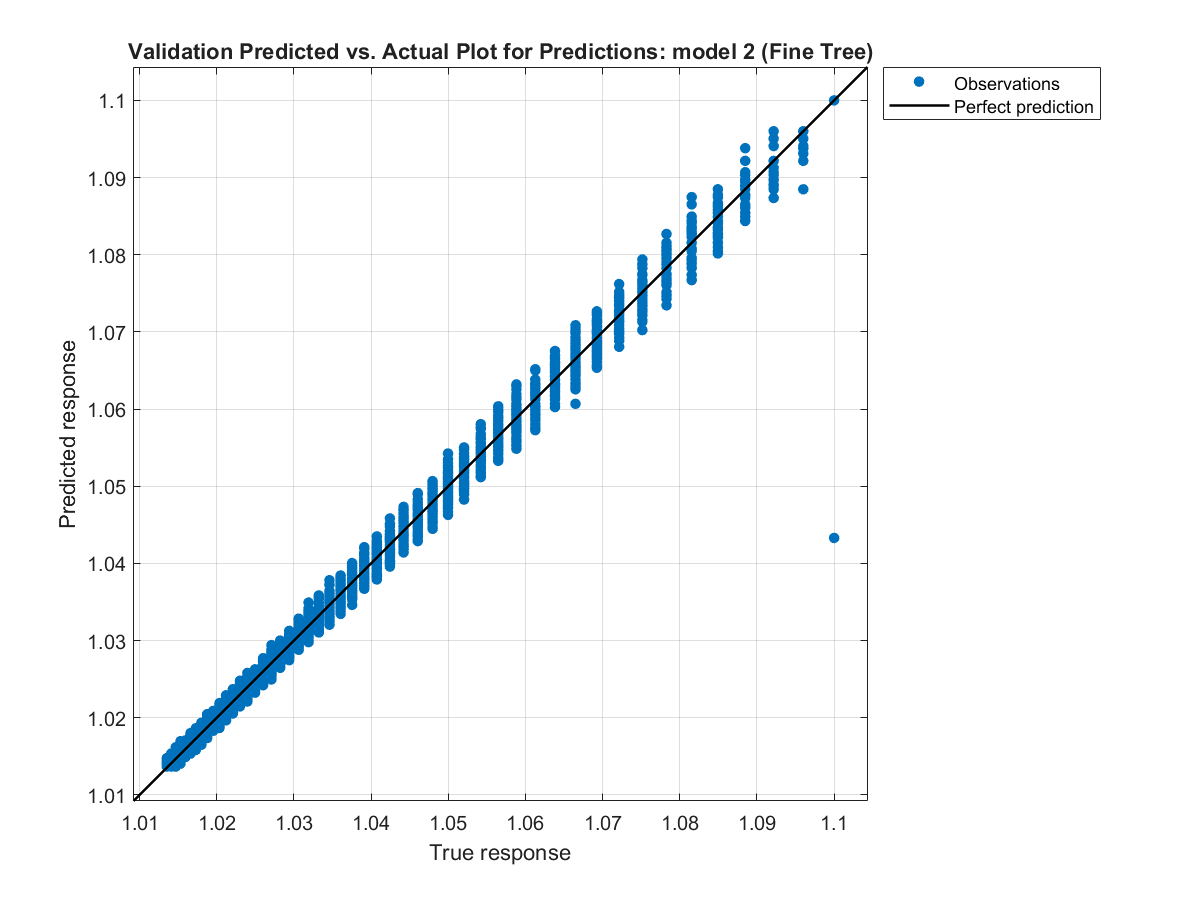

fig = openfig('figure pred vs act.fig');
% Ensure the figure is visible
fig.Visible = 'on';

% Open the original figure
fig = openfig('figure pred vs act.fig');
fig.Visible = 'on';  % Ensure it is visible

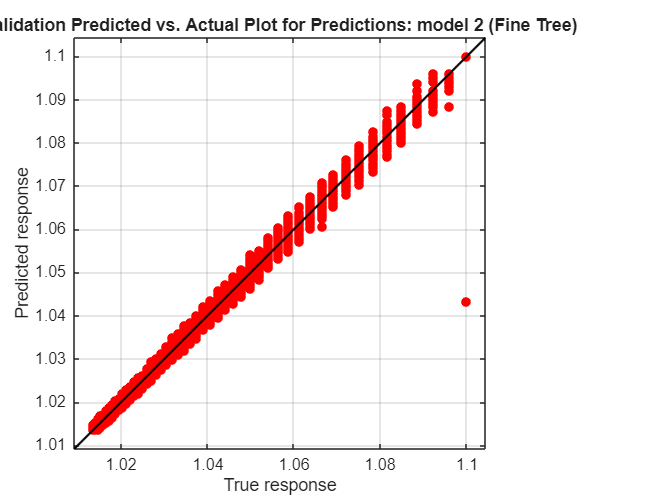

ax = findall(fig, 'Type', 'Axes');
newFig = figure;
copyobj(ax, newFig);

lines = findall(newFig, 'Type', 'Line');

% Change the first plot's colour to red
lines(1).Color = [0, 0, 0];  % Red colour (RGB for red)

% Leave the second plot as black
lines(2).Color = [1, 0, 0];  % Black colour (default)

range = linspace(0, 100, 100);
height = linspace(0, 10, 50);  
propagation_factor = exp(-Range / 50) .* exp(-Height / 5); 
incidence_angle = atan(Height ./ Range); 
refractive_index = 1 + 0.0003 * exp(-Height / 5); 